## Input profile

### Define Input Profile

f_input = [10 50 1200 2000];
ASD_input = [0.000125 0.00125 0.00125 0.000125];

### Define Output Profile 

F0 = 10; %initial frequency
Fmax = 2000; % final frequency
t_signal = 4.0; %signal duration

### Interpolate Input Profile

Fr = 1/t_signal;
Fs = 2*f_input(end);

f = 0:Fr:Fs/2;
PSD = exp(interp1(log(f_input), log(ASD_input), log(f), 'linear'));
PSD(f<F0) = 0;
PSD(f>Fmax) = 0;


Grms = sqrt(trapz(PSD)*Fr);

### plot Input Profile

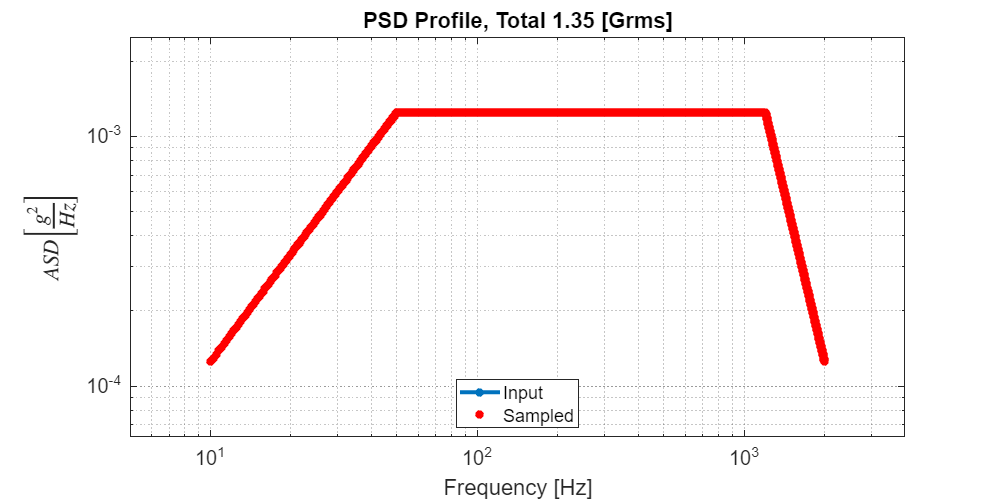

figure('Position',[0 0 1000 500])
loglog(f_input, ASD_input, '-*','LineWidth',3, 'DisplayName',  'Input');
hold on
loglog(f, PSD, 'r*','LineWidth',3, 'DisplayName','Sampled');
grid minor
xlim([0.5*min(f_input) 2*max(f_input)])
ylim([0.5*min(ASD_input) 2*max(ASD_input)])
ylabel('$ASD \left[\frac{g^2}{Hz}\right]$', 'Interpreter','latex')
xlabel('Frequency [Hz]')
title(sprintf('PSD Profile, Total %.2f [Grms]', Grms))
legend('show', 'Location','best')

set(gca, 'fontsize', 15)

## Time SIgnal Reconstruction

t = 0:1/Fs:t_signal;
t = t(1:end-1);

### PSD -> One Sided Amplitude

X1 = zeros(size(PSD));

X1(1) = sqrt(Fr*PSD(1));
X1(2:end) = sqrt(2*Fr*PSD(2:end));

### Phase Randomization

Xphase = randn(size(X1))*(2*pi);

### One Sided Amplitude/Phase to Double-Sided Real/Imag

X1(2:end-1) = X1(2:end-1)/2;
Xreal = X1.*cos(Xphase);
Ximag = X1.*sin(Xphase);

X2 = [Xreal + 1i*Ximag conj(flip(Xreal(2:end-1) + 1i*Ximag(2:end-1)))];

DFT = numel(X2) * X2;

### Frequency Domain -> Time Domain

s = ifft(DFT);

Grms_t = rms(s);

### Plot Results

figure('Position',[0 0 1000 500])
plot(t, s, 'LineWidth',2);

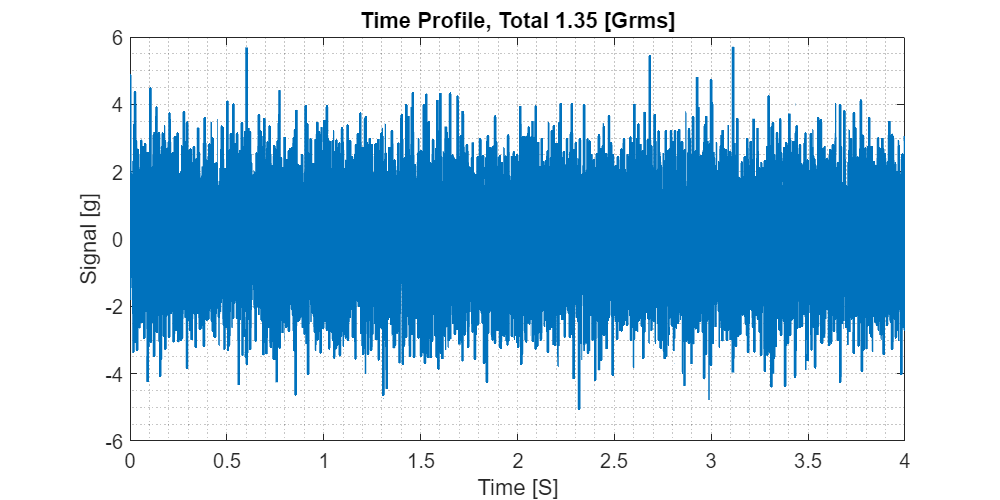

grid minor
% xlim([0.5*min(f_input) 2*max(f_input)])
% ylim([0.5*min(ASD_input) 2*max(ASD_input)])
ylabel('Signal [g]')
xlabel('Time [S]')
title(sprintf('Time Profile, Total %.2f [Grms]', Grms_t))

set(gca, 'fontsize', 15)

## Bonus - Time to PSD

[Pxx,F] = pwelch(s, ones(size(s)), 0, length(s), Fs);

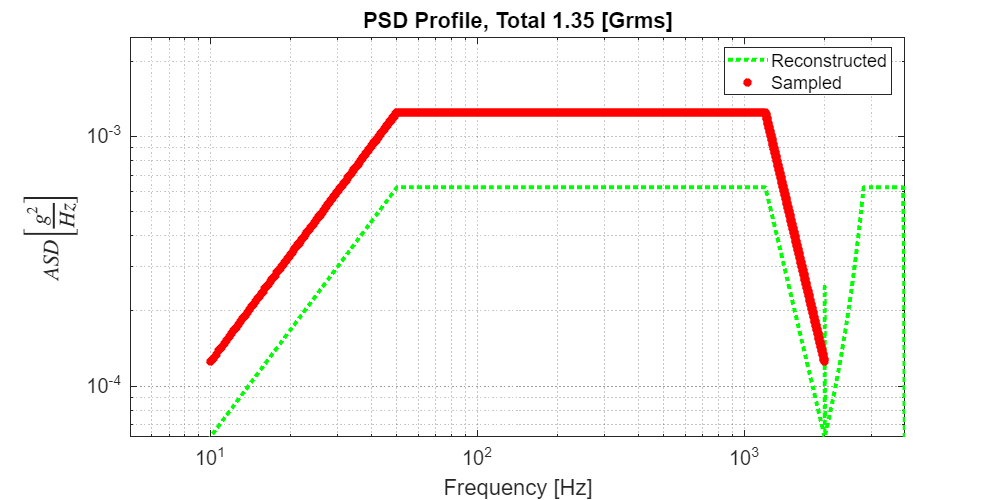

figure('Position',[0 0 1000 500])
loglog(F, Pxx, 'g:','LineWidth',3, 'DisplayName',  'Reconstructed');
hold on
loglog(f, PSD, 'r*','LineWidth',3, 'DisplayName','Sampled');
grid minor
xlim([0.5*min(f_input) 2*max(f_input)])
ylim([0.5*min(ASD_input) 2*max(ASD_input)])
ylabel('$ASD \left[\frac{g^2}{Hz}\right]$', 'Interpreter','latex')
xlabel('Frequency [Hz]')
title(sprintf('PSD Profile, Total %.2f [Grms]', Grms))
legend('show', 'Location','best')

set(gca, 'fontsize', 15)